# XT SPIFI SDI

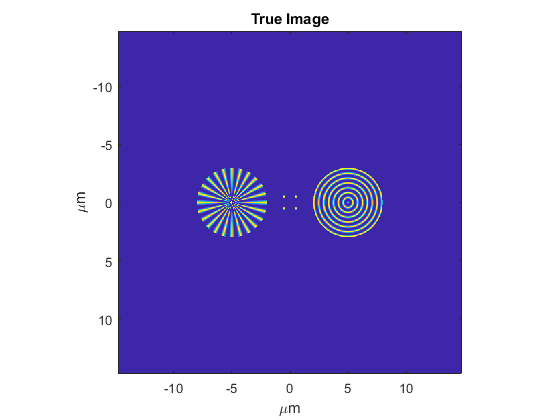

addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SPIFIandCHIRPTSims")
addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SDI\MPSFIFforSDI")
clear variables
%load grids

x=load('xspatvecXT.mat');
x=x.Expression1;
fx=load('xspatfreqXT.mat');
fx=fx.Expression1;
y=load('yspatvecXT.mat');
y=y.Expression1;
fy=load('yspatfreqXT.mat');
fy=fy.Expression1;
trueimage=load("trueimageXT.mat");
trueimage=trueimage.Expression1;
figure; imagesc(x,y,trueimage)
xlabel('\mum')
ylabel('\mum')
axis square
title('True Image')

% Noise free ones
% for jj=1:4
%     s=load(strcat('imgN2',num2str(jj),'.mat'));
%     imgN2(:,:,jj)=s.Expression1;
% end
for jj=1:6
    s=load(strcat('imgNFXT3',num2str(jj),'.mat'));
    imgNFXT3(:,:,jj)=s.Expression1;
end    
% Normalized Versions
% for jj=1:4
%     
%     imgN2N(:,:,jj)=Norm(imgN2(:,:,jj));
% end
for jj=1:6
    
    imgNFXT3N(:,:,jj)=Norm(imgNFXT3(:,:,jj));
end 

figure;
t=tiledlayout(3,3)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


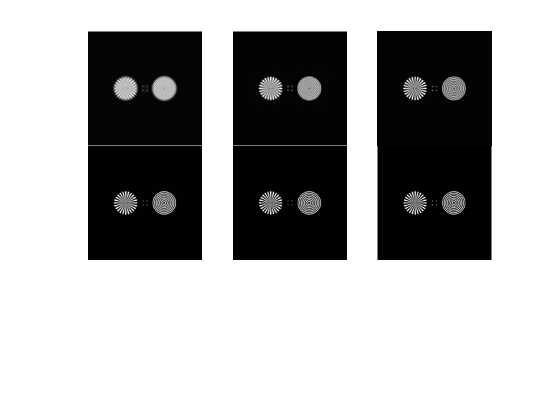

colormap gray
nexttile
imagesc(imgNFXT3(:,:,1))
axis square
axis off
nexttile
imagesc(imgNFXT3(:,:,2))
axis square
axis off
nexttile
imagesc(imgNFXT3(:,:,3))
axis square
axis off
nexttile
imagesc(imgNFXT3(:,:,4))
axis square
axis off
nexttile
imagesc(imgNFXT3(:,:,5))
axis square
axis off
nexttile
imagesc(imgNFXT3(:,:,6))
axis square
axis off
t.TileSpacing = 'none';


for jj=1:6
    s=load(strcat('OTFXT3',num2str(jj),'.mat'));
    OTFXT3(:,:,jj)=s.Expression1;
end    

Also Load Normal OTF's

for jj=1:4
    s=load(strcat('OTF2',num2str(jj),'.mat'));
    OTF2(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('OTF3',num2str(jj),'.mat'));
    OTF3(:,:,jj)=s.Expression1;
end   

figure;
t=tiledlayout(3,3)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


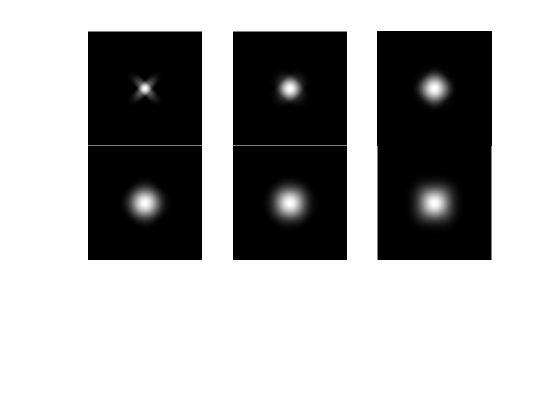

colormap gray
nexttile
imagesc(OTFXT3(:,:,1))
axis square
axis off
nexttile
imagesc(OTFXT3(:,:,2))
axis square
axis off
nexttile
imagesc(OTFXT3(:,:,3))
axis square
axis off
nexttile
imagesc(OTFXT3(:,:,4))
axis square
axis off
nexttile
imagesc(OTFXT3(:,:,5))
axis square
axis off
nexttile
imagesc(OTFXT3(:,:,6))
axis square
axis off
t.TileSpacing = 'none';

for ii=1:6
    PSFXT3(:,:,ii)=abs(ifftshift(ifft2(OTFXT3(:,:,ii))));
end
for ii=1:6
    PSFXT3N(:,:,ii)=Norm(PSFXT3(:,:,ii));
end

figure;
t=tiledlayout(3,3)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


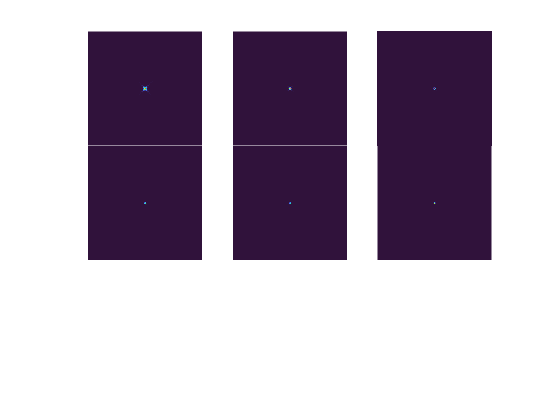

colormap Turbo
nexttile
imagesc(PSFXT3(:,:,1))
axis square
axis off
nexttile
imagesc(PSFXT3(:,:,2))
axis square
axis off
nexttile
imagesc(PSFXT3(:,:,3))
axis square
axis off
nexttile
imagesc(PSFXT3(:,:,4))
axis square
axis off
nexttile
imagesc(PSFXT3(:,:,5))
axis square
axis off
nexttile
imagesc(PSFXT3(:,:,6))
axis square
axis off
t.TileSpacing = 'none';

s=size(PSFXT3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSFXT3N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgNFXT3,[s(1) s(1)*s(3)]);
%bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=4000;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 5389.978057 seconds.


clear recMPIMNXT3 errorrecrecMPIMNXT3
recMPIMNXT3=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 1.3629e-06

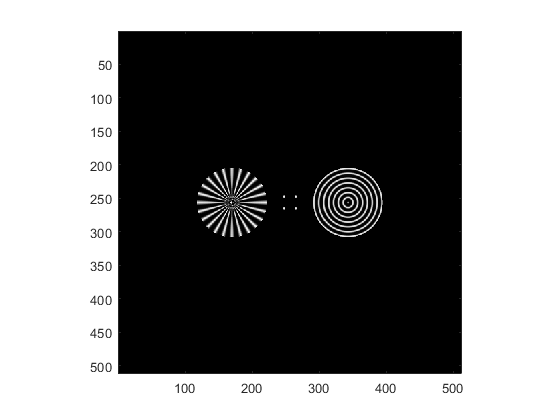

for ii=1:size(recMPIMNXT3,3)
    errorrecrecMPIMNXT3(ii)=immse(Norm(trueimage),Norm(recMPIMNXT3(:,:,ii)));
end

[eval locm]=min(errorrecrecMPIMNXT3);
figure; imagesc(recMPIMNXT3(:,:,locm))
axis square
colormap gray

save('imgNXT3ReconUnCorrNoise.mat','recMPIMNXT3','-v7.3','-nocompression');

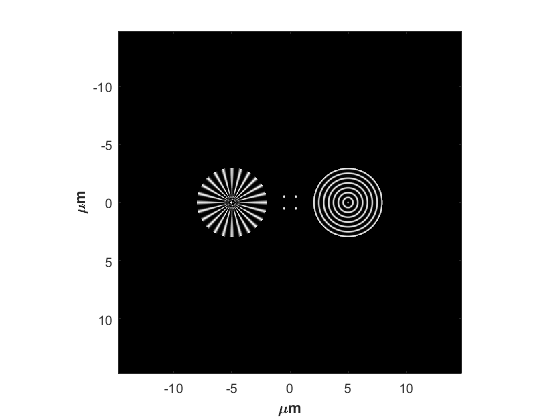

figure; imagesc(x,x,recMPIMNXT3(:,:,locm))
axis square
colormap gray
xlabel('\mum','FontWeight',"bold")
ylabel('\mum','FontWeight',"bold")

#### XT Noise Modeling

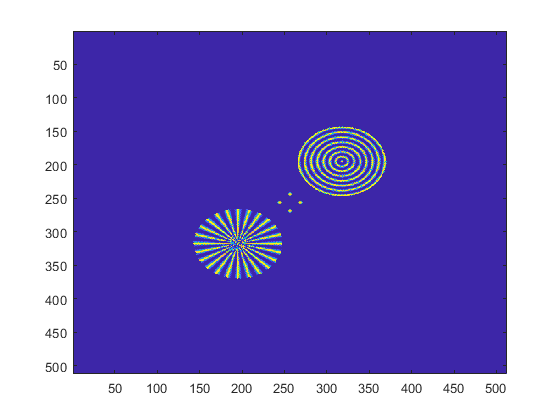

trueimage45=imrotate(trueimage,45,'crop');
trueimagem45=imrotate(trueimage,-45,'crop');
f_x_Object45=(fftshift(fft(trueimage45,[],2),2));
f_x_Objectm45=(fftshift(fft(trueimagem45,[],2),2));
figure; imagesc(trueimage45)

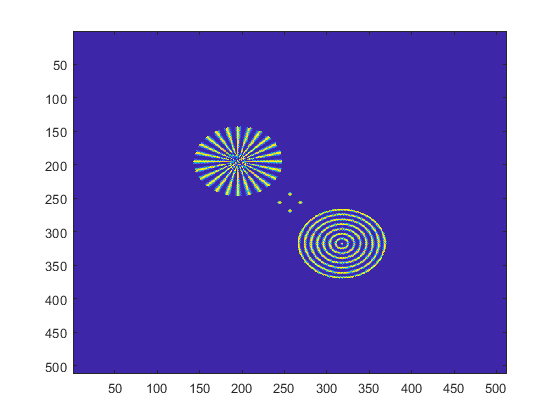

figure; imagesc(trueimagem45)

OTFs in x and y

for jj=1:4
for ii=1:512
    OTF2x(ii,:,jj)=OTF2(end/2,:,jj);
end
end

for jj=1:6
for ii=1:512
    OTF3x(ii,:,jj)=OTF3(end/2,:,jj);
end
end

for jj=1:4
for ii=1:512
    OTF2yy(:,ii,jj)=OTF2(:,end/2,jj);
end
end

for jj=1:6
for ii=1:512
    OTF3yy(:,ii,jj)=OTF3(:,ii,jj);
end
end

Generate signals for each rotation

for ii=1:4
    sig2Gx45(:,:,ii)=OTF2x(:,:,ii).*f_x_Object45;
end
for ii=1:4
    sig2Gv345(:,:,ii)=ifft(((((OTF2yy(:,:,ii).*fftshift(fft(sig2Gx45(:,:,ii),[],1),1))))),[],1);
end
for ii=1:6
    sig3Gx45(:,:,ii)=OTF3x(:,:,ii).*f_x_Object45;
end
for ii=1:6
    sig3Gv345(:,:,ii)=ifft(((((OTF3yy(:,:,ii).*fftshift(fft(sig3Gx45(:,:,ii),[],1),1))))),[],1);
end

for ii=1:4
    sig2Gxm45(:,:,ii)=OTF2x(:,:,ii).*f_x_Objectm45;
end
for ii=1:4
    sig2Gv3m45(:,:,ii)=ifft(((((OTF2yy(:,:,ii).*fftshift(fft(sig2Gxm45(:,:,ii),[],1),1))))),[],1);
end
for ii=1:6
    sig3Gxm45(:,:,ii)=OTF3x(:,:,ii).*f_x_Objectm45;
end
for ii=1:6
    sig3Gv3m45(:,:,ii)=ifft(((((OTF3yy(:,:,ii).*fftshift(fft(sig3Gxm45(:,:,ii),[],1),1))))),[],1);
end

Generate Noisy Images

o1=max(max(abs(sig2Gv345(:,:,1))));
maxphtcnt=255000;
for ii=1:4
    imNGXT245(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv345(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end
o1=max(max(abs(sig3Gv345(:,:,1))));
maxphtcnt=255000;
for ii=1:6
    imNGXT345(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv345(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end

o1=max(max(abs(sig2Gv3m45(:,:,1))));
maxphtcnt=255000;
for ii=1:4
    imNGXT2m45(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv3m45(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end
o1=max(max(abs(sig3Gv3m45(:,:,1))));
maxphtcnt=255000;
for ii=1:6
    imNGXT3m45(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3m45(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end

Rotate back to center and add

for ii=1:4
    imgNGXT2(:,:,ii)=(imrotate(imNGXT2m45(:,:,ii),45,'crop')+imrotate(imNGXT245(:,:,ii),-45,'crop'))/2;
end
for ii=1:6
    imgNGXT3(:,:,ii)=(imrotate(imNGXT3m45(:,:,ii),45,'crop')+imrotate(imNGXT345(:,:,ii),-45,'crop'))/2;
end

figure;
t=tiledlayout(3,3)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


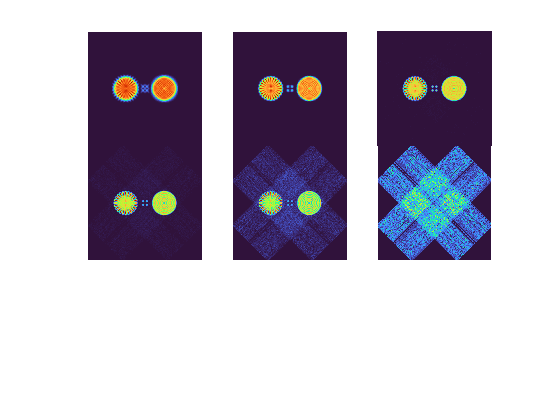

colormap Turbo
nexttile
imagesc(imgNGXT3(:,:,1))
axis square
axis off
nexttile
imagesc(imgNGXT3(:,:,2))
axis square
axis off
nexttile
imagesc(imgNGXT3(:,:,3))
axis square
axis off
nexttile
imagesc(imgNGXT3(:,:,4))
axis square
axis off
nexttile
imagesc(imgNGXT3(:,:,5))
axis square
axis off
nexttile
imagesc(imgNGXT3(:,:,6))
axis square
axis off
t.TileSpacing = 'none';

Should add noise to missing triangle chuncks

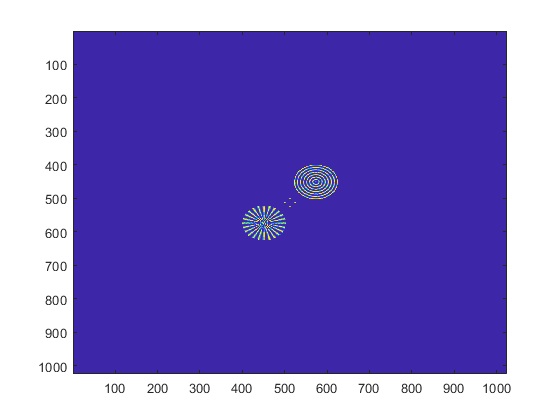

padn=256;
trueimage45p=imrotate(padarray(trueimage,[padn padn],0,'both'),45,'crop');
trueimagem45p=imrotate(padarray(trueimage,[padn padn],0,'both'),-45,'crop');
f_x_Object45p=(fftshift(fft(trueimage45p,[],2),2));
f_x_Objectm45p=(fftshift(fft(trueimagem45p,[],2),2));
figure; imagesc(trueimage45p)

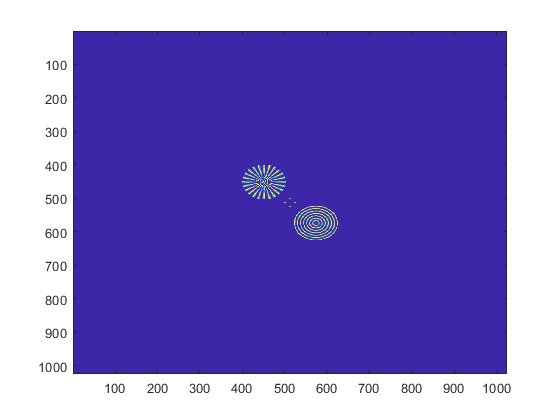

figure; imagesc(trueimagem45p)

OTF2xp=padarray(OTF2x,[padn padn],0,'both');
OTF3xp=padarray(OTF3x,[padn padn],0,'both');
OTF2yyp=padarray(OTF2yy,[padn padn],0,'both');
OTF3yyp=padarray(OTF3yy,[padn padn],0,'both');

for ii=1:4
    sig2Gx45p(:,:,ii)=OTF2xp(:,:,ii).*f_x_Object45p;
end
for ii=1:4
    sig2Gv345p(:,:,ii)=ifft(((((OTF2yyp(:,:,ii).*fftshift(fft(sig2Gx45p(:,:,ii),[],1),1))))),[],1);
end
for ii=1:6
    sig3Gx45p(:,:,ii)=OTF3xp(:,:,ii).*f_x_Object45p;
end
for ii=1:6
    sig3Gv345p(:,:,ii)=ifft(((((OTF3yyp(:,:,ii).*fftshift(fft(sig3Gx45p(:,:,ii),[],1),1))))),[],1);
end

for ii=1:4
    sig2Gxm45p(:,:,ii)=OTF2xp(:,:,ii).*f_x_Objectm45p;
end
for ii=1:4
    sig2Gv3m45p(:,:,ii)=ifft(((((OTF2yyp(:,:,ii).*fftshift(fft(sig2Gxm45p(:,:,ii),[],1),1))))),[],1);
end
for ii=1:6
    sig3Gxm45p(:,:,ii)=OTF3xp(:,:,ii).*f_x_Objectm45p;
end
for ii=1:6
    sig3Gv3m45p(:,:,ii)=ifft(((((OTF3yyp(:,:,ii).*fftshift(fft(sig3Gxm45p(:,:,ii),[],1),1))))),[],1);
end

% Do this by zero padding everything first, then take out center chunck
% First padding signals
% padn=256;
% sig2Gv345p=padarray(sig2Gv345,[padn padn],0,'both');
% sig2Gv3m45p=padarray(sig2Gv3m45,[padn padn],0,'both');
% sig3Gv345p=padarray(sig3Gv345,[padn padn],0,'both');
% sig3Gv3m45p=padarray(sig3Gv3m45,[padn padn],0,'both');
clear imNGXT245p imNGXT2m45p imNGXT345p imNGXT3m45p
% Generate noisy images
o1=max(max(abs(sig2Gv345p(:,:,1))));
maxphtcnt=255000;
for ii=1:4
    imNGXT245p(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv345p(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end
o1=max(max(abs(sig3Gv345p(:,:,1))));
maxphtcnt=255000;
for ii=1:6
    imNGXT345p(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv345p(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end

o1=max(max(abs(sig2Gv3m45p(:,:,1))));
maxphtcnt=255000;
for ii=1:4
    imNGXT2m45p(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv3m45p(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end
o1=max(max(abs(sig3Gv3m45p(:,:,1))));
maxphtcnt=255000;
for ii=1:6
    imNGXT3m45p(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3m45p(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end

clear imgNGXT2p imgNGXT3p
for ii=1:4
    imgNGXT2p(:,:,ii)=(imrotate(imNGXT2m45p(:,:,ii),45,'crop')+imrotate(imNGXT245p(:,:,ii),-45,'crop'))/2;
end
for ii=1:6
    imgNGXT3p(:,:,ii)=(imrotate(imNGXT3m45p(:,:,ii),45,'crop')+imrotate(imNGXT345p(:,:,ii),-45,'crop'))/2;
end

figure;
t=tiledlayout(3,3)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


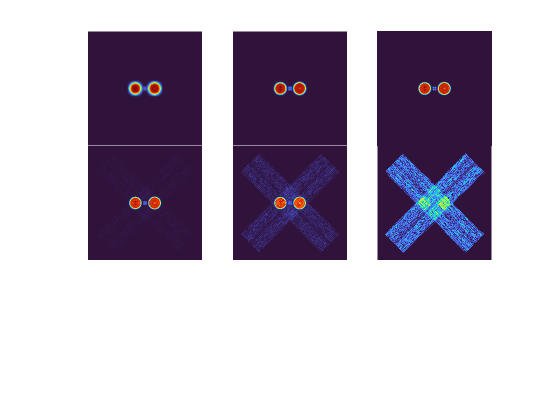

colormap Turbo
nexttile
imagesc(imgNGXT3p(:,:,1))
axis square
axis off
nexttile
imagesc(imgNGXT3p(:,:,2))
axis square
axis off
nexttile
imagesc(imgNGXT3p(:,:,3))
axis square
axis off
nexttile
imagesc(imgNGXT3p(:,:,4))
axis square
axis off
nexttile
imagesc(imgNGXT3p(:,:,5))
axis square
axis off
nexttile
imagesc(imgNGXT3p(:,:,6))
axis square
axis off
t.TileSpacing = 'none';

Not working... Getting extra blurring

tritry=imgNGXT3(:,:,6);
tritry(1:149,364:512)=tritry(1:149,364:512)+tritry(363:511,1:149);
tritry(364:512,1:149)=tritry(1:149,363:511);
tritry(1:149,1:149)=tritry(1:149,1:149)+circshift(tritry(363:511,363:511),-1);%circshift(tritry(363:509,363:509),-1)
tritry(149,1:149)=imgNGXT3(149,1:149,6);
tritry(363:511,363:511)=tritry(1:149,1:149);

for ii=1:6
    tritry=imgNGXT3(:,:,ii);
tritry(1:149,364:512)=tritry(1:149,364:512)+tritry(363:511,1:149);
tritry(364:512,1:149)=tritry(1:149,363:511);
tritry(1:149,1:149)=tritry(1:149,1:149)+circshift(tritry(363:511,363:511),-1);%circshift(tritry(363:509,363:509),-1)
tritry(149,1:149)=imgNGXT3(149,1:149,ii);
tritry(363:511,363:511)=tritry(1:149,1:149);
imgNGXT3c(:,:,ii)=tritry;
end

for ii=1:4
    tritry=imgNGXT2(:,:,ii);
tritry(1:149,364:512)=tritry(1:149,364:512)+tritry(363:511,1:149);
tritry(364:512,1:149)=tritry(1:149,363:511);
tritry(1:149,1:149)=tritry(1:149,1:149)+circshift(tritry(363:511,363:511),-1);%circshift(tritry(363:509,363:509),-1)
tritry(149,1:149)=imgNGXT2(149,1:149,ii);
tritry(363:511,363:511)=tritry(1:149,1:149);
imgNGXT2c(:,:,ii)=tritry;
end

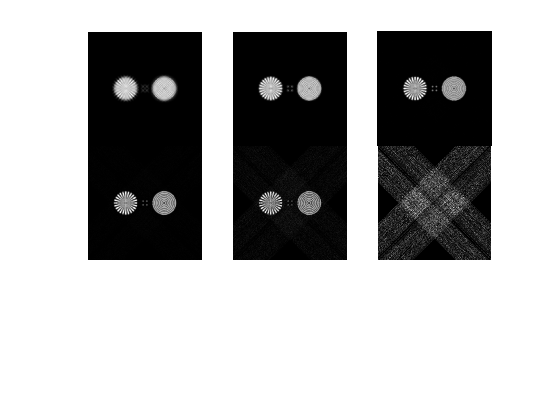

figure;
t=tiledlayout(3,3);
colormap gray
nexttile
imagesc(imgNGXT3c(:,:,1))
axis square
axis off
nexttile
imagesc(imgNGXT3c(:,:,2))
axis square
axis off
nexttile
imagesc(imgNGXT3c(:,:,3))
axis square
axis off
nexttile
imagesc(imgNGXT3c(:,:,4))
axis square
axis off
nexttile
imagesc(imgNGXT3c(:,:,5))
axis square
axis off
nexttile
imagesc(imgNGXT3c(:,:,6))
axis square
axis off
t.TileSpacing = 'none';

for ii=1:6
    imgNGXT3cN(:,:,ii)=Norm(imgNGXT3c(:,:,ii));
end

s=size(PSFXT3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSFXT3N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgNGXT3cN,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=100;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 143.214069 seconds.


clear recMPIMN3XT errorrecrecMPIMN3XT
recMPIMN3XT=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0095

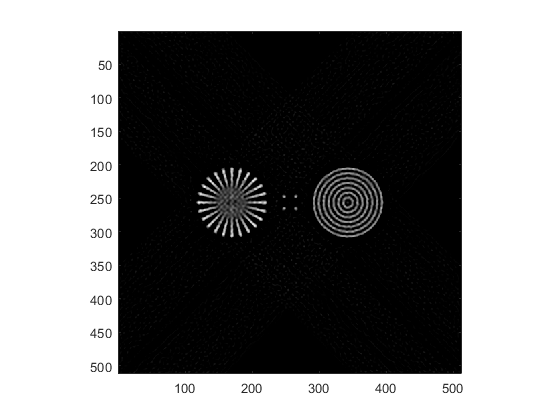

for ii=1:size(recMPIMN3XT,3)
    errorrecrecMPIMN3XT(ii)=immse(Norm(trueimage),Norm(recMPIMN3XT(200:311,112:400,ii)));
end

[evalXT locmXT]=min(errorrecrecMPIMN3XT);
figure; imagesc(recMPIMN3XT(:,:,locmXT))
axis square
colormap gray

save('imgNXT3Reconphtcnt255000.mat','recMPIMN3XT','-v7.3','-nocompression');

o1=max(max(mean(real(sum(sig2Gv345,3)+9),2)));
%o1=max(max(abs(sig2Gv345(:,:,1))));
maxphtcnt=255000*4;
for ii=1:4
    imNGXT245(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv345(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end
o1=max(max(mean(real(sum(sig3Gv345,3)+9),2)));
%o1=max(max(abs(sig3Gv345(:,:,1))));
%maxphtcnt=255000;
for ii=1:6
    imNGXT345(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv345(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end
o1=max(max(mean(real(sum(sig2Gv3m45,3)+9),2)));
%o1=max(max(abs(sig2Gv3m45(:,:,1))));
%maxphtcnt=255000;
for ii=1:4
    imNGXT2m45(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv3m45(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end
o1=max(max(mean(real(sum(sig3Gv3m45,3)+9),2)));
%o1=max(max(abs(sig3Gv3m45(:,:,1))));
%maxphtcnt=255000;
for ii=1:6
    imNGXT3m45(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3m45(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end

Rotate back to center and add

for ii=1:4
    imgNGXT2(:,:,ii)=(imrotate(imNGXT2m45(:,:,ii),45,'crop')+imrotate(imNGXT245(:,:,ii),-45,'crop'))/2;
end
for ii=1:6
    imgNGXT3(:,:,ii)=(imrotate(imNGXT3m45(:,:,ii),45,'crop')+imrotate(imNGXT345(:,:,ii),-45,'crop'))/2;
end


for ii=1:6
    tritry=imgNGXT3(:,:,ii);
tritry(1:149,364:512)=tritry(1:149,364:512)+tritry(363:511,1:149);
tritry(364:512,1:149)=tritry(1:149,363:511);
tritry(1:149,1:149)=tritry(1:149,1:149)+circshift(tritry(363:511,363:511),-1);%circshift(tritry(363:509,363:509),-1)
tritry(149,1:149)=imgNGXT3(149,1:149,ii);
tritry(363:511,363:511)=tritry(1:149,1:149);
imgNGXT3c(:,:,ii)=tritry;
end

for ii=1:4
    tritry=imgNGXT2(:,:,ii);
tritry(1:149,364:512)=tritry(1:149,364:512)+tritry(363:511,1:149);
tritry(364:512,1:149)=tritry(1:149,363:511);
tritry(1:149,1:149)=tritry(1:149,1:149)+circshift(tritry(363:511,363:511),-1);%circshift(tritry(363:509,363:509),-1)
tritry(149,1:149)=imgNGXT2(149,1:149,ii);
tritry(363:511,363:511)=tritry(1:149,1:149);
imgNGXT2c(:,:,ii)=tritry;
end

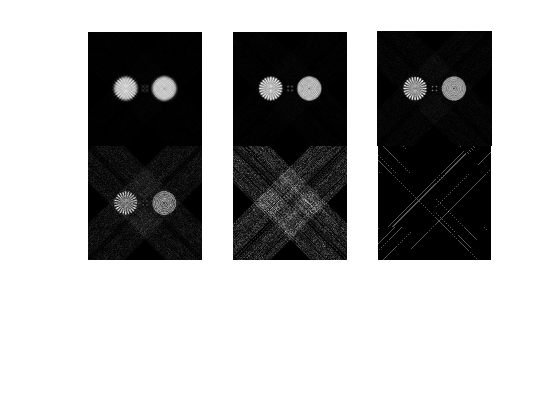

figure;
t=tiledlayout(3,3);
colormap gray
nexttile
imagesc(imgNGXT3c(:,:,1))
axis square
axis off
nexttile
imagesc(imgNGXT3c(:,:,2))
axis square
axis off
nexttile
imagesc(imgNGXT3c(:,:,3))
axis square
axis off
nexttile
imagesc(imgNGXT3c(:,:,4))
axis square
axis off
nexttile
imagesc(imgNGXT3c(:,:,5))
axis square
axis off
nexttile
imagesc(imgNGXT3c(:,:,6))
axis square
axis off
t.TileSpacing = 'none';

for ii=1:6
    imgNGXT3cN(:,:,ii)=Norm(imgNGXT3c(:,:,ii));
end

s=size(PSFXT3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSFXT3N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgNGXT3cN,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=100;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 137.572022 seconds.


clear recMPIMN3XT errorrecrecMPIMN3XT
recMPIMN3XT=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm);
for ii=1:size(recMPIMN3XT,3)
    errorrecrecMPIMN3XT(ii)=immse(Norm(trueimage(200:311,112:400)),Norm(recMPIMN3XT(200:311,112:400,ii)));
end

[evalXT locmXT]=min(errorrecrecMPIMN3XT);
evalXT

evalXT = 0.0332

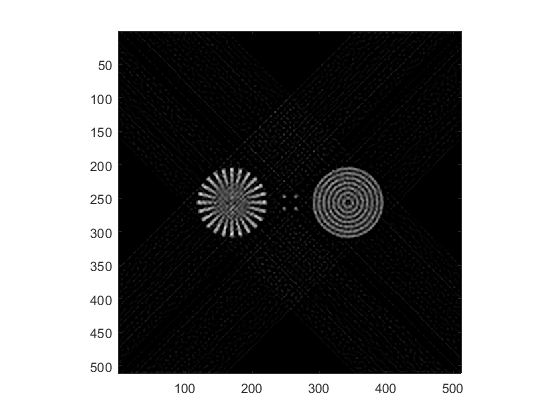

figure; imagesc(recMPIMN3XT(:,:,locmXT))
axis square
colormap gray

Noise Free

% o1=max(max(abs(sig2Gv345(:,:,1))));
% maxphtcnt=255000;
for ii=1:4
    imNFGXT245(:,:,ii)=fftshift(abs(ifftshift(ifft(sig2Gv345(:,:,ii),[],2),2)),2);
end
% o1=max(max(abs(sig3Gv345(:,:,1))));
%maxphtcnt=255000;
for ii=1:6
    imNFGXT345(:,:,ii)=fftshift(abs(ifftshift(ifft(sig3Gv345(:,:,ii),[],2),2)),2);
end

% o1=max(max(abs(sig2Gv3m45(:,:,1))));
%maxphtcnt=255000;
for ii=1:4
    imNFGXT2m45(:,:,ii)=fftshift(abs(ifftshift(ifft(sig2Gv3m45(:,:,ii),[],2),2)),2);
end
% o1=max(max(abs(sig3Gv3m45(:,:,1))));
%maxphtcnt=255000;
for ii=1:6
    imNFGXT3m45(:,:,ii)=fftshift(abs(ifftshift(ifft(sig3Gv3m45(:,:,ii),[],2),2)),2);
end

Rotate back to center and add

for ii=1:4
    imgNFGXT2(:,:,ii)=(imrotate(imNFGXT2m45(:,:,ii),45,'crop')+imrotate(imNFGXT245(:,:,ii),-45,'crop'))/2;
end
for ii=1:6
    imgNFGXT3(:,:,ii)=(imrotate(imNFGXT3m45(:,:,ii),45,'crop')+imrotate(imNFGXT345(:,:,ii),-45,'crop'))/2;
end

Extract Noise

% o1=max(max(abs(sig2Gv345(:,:,1))));
% for ii=1:4
%     G2N(:,:,ii)=imNG2(:,:,ii)-imgNFGXT2(:,:,ii)*maxphtcnt/o1;
% end
%o1=max(max(abs(sig3Gv345(:,:,1))));
o1=max(max(mean(real(sum(sig2Gv3m45,3)+9),2)));
for ii=1:6
    G3XTN(:,:,ii)=imgNGXT3c(:,:,ii)-imgNFGXT3(:,:,ii)*maxphtcnt/o1;
end

Add Noise Back in

o1=max(max(abs(sig3Gv345(:,:,1))));
for ii=1:6
imNGXT3v2(:,:,ii)=G3XTN(:,:,ii)+imgNFGXT3(:,:,ii)*maxphtcnt/o1;
end

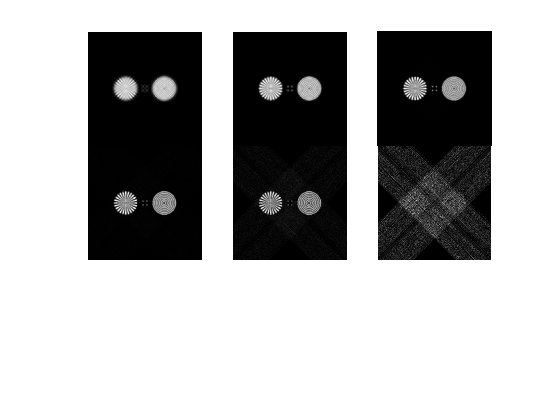

figure;
t=tiledlayout(3,3);
colormap gray
nexttile
imagesc(imNGXT3v2(:,:,1))
axis square
axis off
nexttile
imagesc(imNGXT3v2(:,:,2))
axis square
axis off
nexttile
imagesc(imNGXT3v2(:,:,3))
axis square
axis off
nexttile
imagesc(imNGXT3v2(:,:,4))
axis square
axis off
nexttile
imagesc(imNGXT3v2(:,:,5))
axis square
axis off
nexttile
imagesc(imNGXT3v2(:,:,6))
axis square
axis off
t.TileSpacing = 'none';

for ii=1:6
    imNGXT3v2N(:,:,ii)=Norm(imNGXT3v2(:,:,ii));
end

s=size(PSFXT3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSFXT3N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imNGXT3v2N,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=100;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 141.894759 seconds.


clear recMPIMN3XT errorrecrecMPIMN3XT
recMPIMN3XT=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm);
for ii=1:size(recMPIMN3XT,3)
    errorrecrecMPIMN3XT(ii)=immse(Norm(trueimage(200:311,112:400)),Norm(recMPIMN3XT(200:311,112:400,ii)));
end

[evalXT locmXT]=min(errorrecrecMPIMN3XT);
evalXT

evalXT = 0.0237

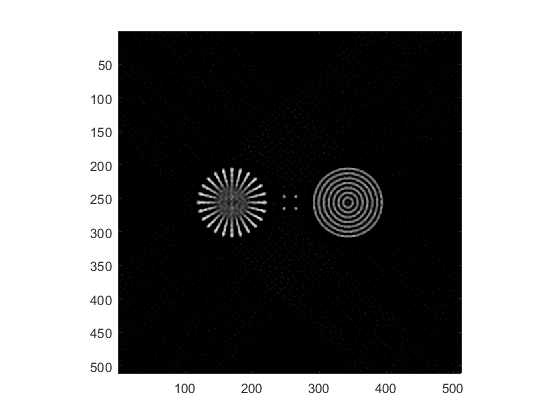

figure; imagesc(recMPIMN3XT(:,:,locmXT))
axis square
colormap gray

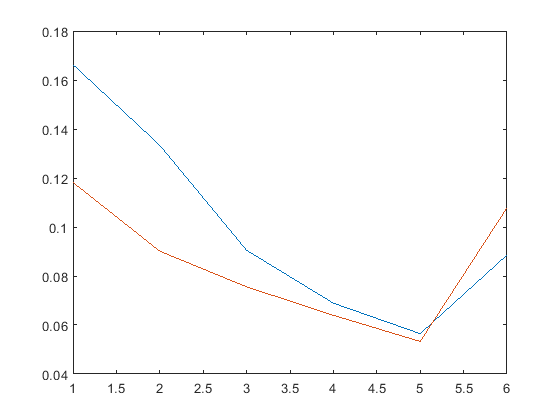

% Error in Each Harmonic image (Adding Noise to Randy's)
for ii=1:size(imNGXT3v2,3)
    errorharmsGNXT3(ii)=immse(Norm(imNGXT3v2(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
for ii=1:size(imNG3v2,3)
    errorharmsimNG3v2(ii)=immse(Norm(imNG3v2(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end

for ii=1:size(imgNFXT3,3)
    errorharmsimgNFXT3(ii)=immse(Norm(imgNFXT3(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
for ii=1:size(imgNF3,3)
    errorharmsimimgNF3(ii)=immse(Norm(imgNF3(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end

% for ii=1:size(imgN2new1N,3)
%     errorharmsRGN2(ii)=immse(Norm(imgN2new1N(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
%     
% end
figure; plot(errorharmsGNXT3)
hold on
plot(errorharmsimNG3v2)

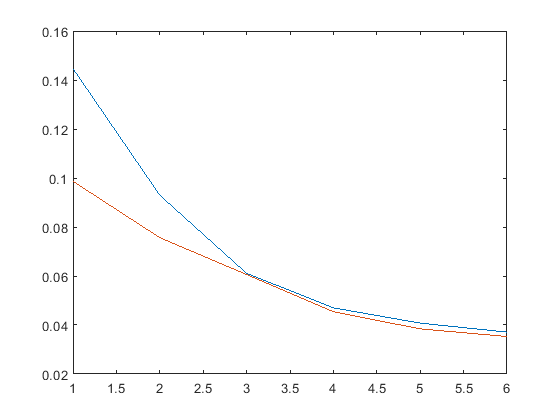


figure; plot(errorharmsimgNFXT3)
hold on
plot(errorharmsimimgNF3)

% figure; plot(errorharmsRGN2)
% % Corresponding error in reconstructions
% eval
% eval2

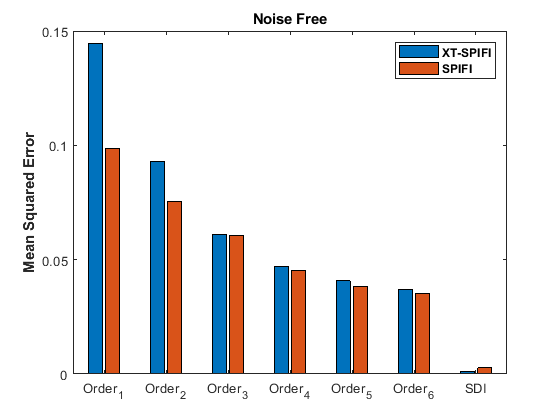

Xn = categorical({'Order_1','Order_2','Order_3','Order_4','Order_5','Order_6','SDI'});

Yn = [errorharmsimgNFXT3(1) errorharmsimimgNF3(1); errorharmsimgNFXT3(2) errorharmsimimgNF3(2); errorharmsimgNFXT3(3) errorharmsimimgNF3(3); errorharmsimgNFXT3(4) errorharmsimimgNF3(4); errorharmsimgNFXT3(5) errorharmsimimgNF3(5); errorharmsimgNFXT3(6) errorharmsimimgNF3(6); immse(Norm(recNFXT3.recMPIMNXT3(200:311,112:400,end)),Norm(trueimage(200:311,112:400))) immse(Norm(NF3(200:311,112:400)),Norm(trueimage(200:311,112:400)));];
figure;
bar(Xn,Yn)
ylabel('Mean Squared Error','FontWeight',"bold")
title('Noise Free','FontWeight',"bold")
legend({'XT-SPIFI','SPIFI'},'FontWeight',"bold")

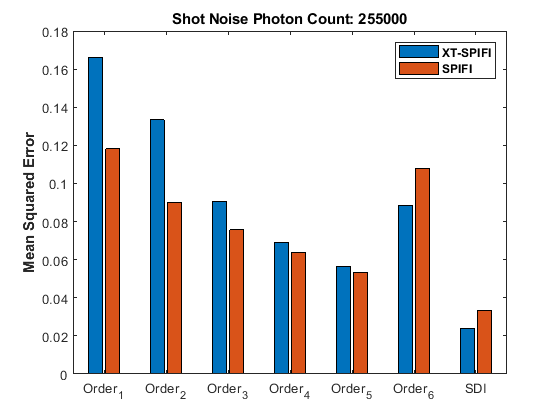

Xn2 = categorical({'Order_1','Order_2','Order_3','Order_4','Order_5','Order_6','SDI'});

Yn2 = [errorharmsGNXT3(1) errorharmsimNG3v2(1); errorharmsGNXT3(2) errorharmsimNG3v2(2); errorharmsGNXT3(3) errorharmsimNG3v2(3); errorharmsGNXT3(4) errorharmsimNG3v2(4); errorharmsGNXT3(5) errorharmsimNG3v2(5); errorharmsGNXT3(6) errorharmsimNG3v2(6); .0238 .0333;];
figure;
bar(Xn2,Yn2)
ylabel('Mean Squared Error','FontWeight',"bold")
title('Shot Noise Photon Count: 255000','FontWeight',"bold")
legend({'XT-SPIFI','SPIFI'},'FontWeight',"bold")